原文链接：https://blog.csdn.net/weixin_44044411/article/details/85891109

在对其进行数字PID控制前，我们需要将这个系统离散化：

由于是数字PID仿真，我们需要选取一个采样时间，本案例选用的是0.005s（注意，采样周期应该小于系统纯滞后时间的0.1倍）。在对其进行数字PID控制前，我们需要将这个系统离散化：

% sys=tf(0.998,[0.021,1]);   %建立被控对象传递函数
% ts=0.005;  %采样时间=0.005s
% dsys=c2d(sys,ts,'z');      %离散化

**dsys **即我们根据采样周期离散化的Z变换系统。首先我们需要提取这个Z变化d那系统的参数方便后面的计算：

% [num,den]=tfdata(dsys,'v');%'v'代表强制以向量的格式（默认为元胞数组）输出num和den

在PID仿真的过程中我们需要求解出时域表达式 ，因此需要借助差分方程解决，对于以下的Z变换：

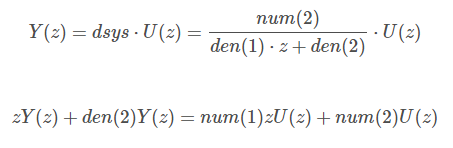

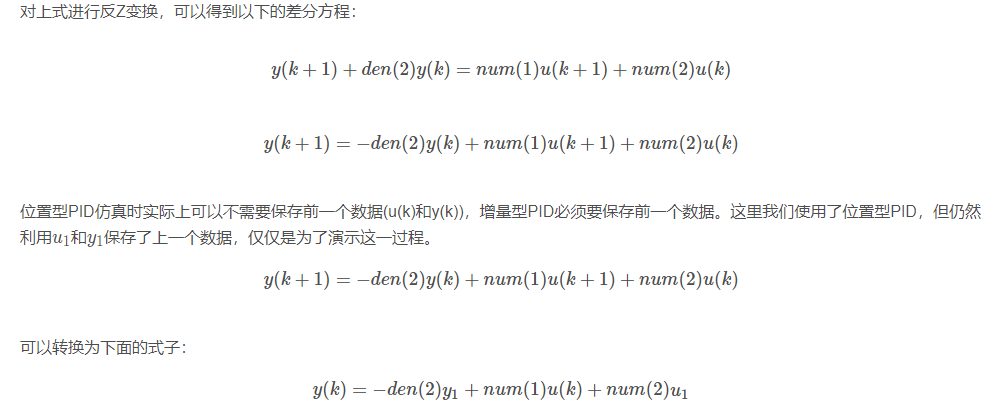

我们的差分方程就这样建立完毕。注意，此差分方程仅仅是描述系统模型的运算规律的，和我们的控制无关。因此是y(k)和u(k)的映射关系。我们下面的控制则是利用负反馈信号e(k)导出u(k)的输出，求解的是控制器u(k)的序列值。

以位置型PID控制为例。将连续的PID控制转换为数字式时，微分环节被用差分代替，积分环节被累加和代替，比例环节则保持不变。

差分的实现非常简单，只需要用e(k+1) − e(k) 。积分的实现在每一次运算的后面都累加原来的误差，即Ee=Ee+e_1;

�

PID控制器构造完毕，我们需要通过r(k)和y(k)得到e(k)，再通过e(k)得出u(k)，进而再求解出y(k)，再结合r(k)求解出e(k),…以此循环，求解出离散的响应点

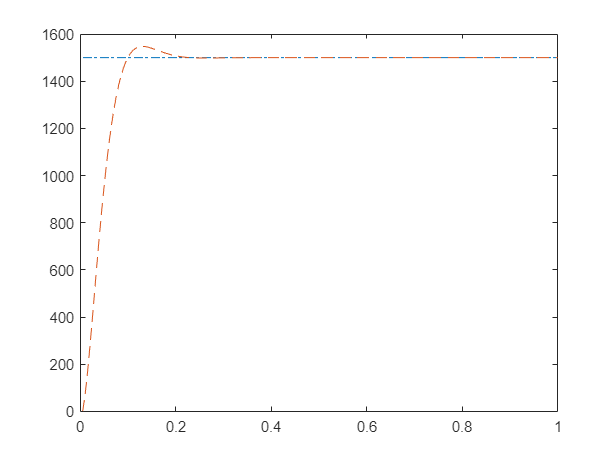


ts=0.005;  %采样时间=0.005s
sys=tf(0.998,[0.021,1]);   %建立被控对象传递函数，即式4.1
dsys=c2d(sys,ts,'z');      %离散化
[num,den]=tfdata(dsys,'v');   %'v'代表强制以向量的格式（默认为元胞数组）输出num和den
e_1=0;      %前一时刻的偏差      
Ee=0;       %累积偏差
u_1=0.0;    %前一时刻的控制量
y_1=0;       %前一时刻的输出

%PID参数
kp=0.22;    
ki=0.13;
kd=0;
u=zeros(1,1000);   %预先分配内存
time=zeros(1,1000);%时刻点（设定1000个）
for k=1:1:1000
    time(k)=k*ts;   %时间参数
    r(k)=1500;      %期望值
    y(k)=-1*den(2)*y_1+num(2)*u_1+num(1)*u(k);%系统响应输出序列
    e(k)=r(k)-y(k);   %误差信号
    u(k)=kp*e(k)+ki*Ee+kd*(e(k)-e_1); %系统PID控制器输出序列
    Ee=Ee+e(k);     %误差的累加和
    u_1=u(k);    	%前一个的控制器输出值
    y_1=y(k);    	%前一个的系统响应输出值
    e_1=e(k);		%前一个误差信号的值
end
%（仅绘制过渡过程的曲线，x坐标限制为[0,1]）
p1=plot(time,r,'-.');xlim([0,1]);hold on;%指令信号的曲线（即期望输入）
p2=plot(time,y,'--');xlim([0,1]);%不含积分分离的PID曲线
hold on;

**比较PID输出，分析参数产生的影响**

一个基本的PID就完成了。下面如果我们想要知道修改PID的三个参数kp,ki,kd会带来什么效果，只需要在程序中修改即可。

为了方便起见，我们建立一个PID的数组，kp,ki,kd每次都取数组的一个值，然后设定一个大循环开始循环仿真。

再利用subplot输出子图的方式将所有的PID效果都输出到一个图进行对比。该代码根据上述代码修改已经很容易，PID比较图的代码如下：

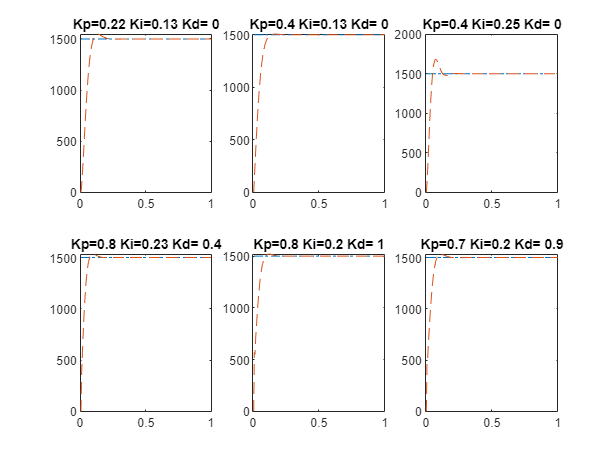

% close all
PID=[0.22,0.13,0;
    0.4,0.13,0;
    0.4,0.25,0;
    0.8,0.23,0.4;
    0.8,0.2,1;
    0.7,0.2,0.9];%初始化PID参数
for pid=1:1:6
    ts=0.005;  %采样时间=0.005s
    sys=tf(0.998,[0.021,1]);   %建立被控对象传递函数，即式4.1
    dsys=c2d(sys,ts,'z');      %离散化
    [num,den]=tfdata(dsys,'v');   %
    e_1=0;      %前一时刻的偏差      
    Ee=0;       %累积偏差
    u_1=0.0;    %前一时刻的控制量
    y_1=0;       %前一时刻的输出
    %PID参数
    kp=PID(pid,1);    
    ki=PID(pid,2);
    kd=PID(pid,3);
    u=zeros(1,1000);
    time=zeros(1,1000);
    for k=1:1:1000
        time(k)=k*ts;   %时间参数
        r(k)=1500;      %给定量
        y(k)=-1*den(2)*y_1+num(2)*u_1+num(1)*u(k);
        e(k)=r(k)-y(k);   %偏差
        u(k)=kp*e(k)+ki*Ee+kd*(e(k)-e_1);   
        Ee=Ee+e(k);    
        u_1=u(k);    
        y_1=y(k);    
        e_1=e(k);
    end
    subplot(2,3,pid);
    p1=plot(time,r,'-.');xlim([0,1]);hold on;
    p2=plot(time,y,'--');xlim([0,1]);
    title(['Kp=',num2str(kp),' Ki=',num2str(ki),' Kd= ',num2str(kd)]);
    hold on;
end

可以发现，修改Kp会造成上升时间的缩短，但是有可能也会带来较大的超调。积分的增加是一个严重的滞后环节，会减小相位裕度，也会带来超调（超调量并不是绝对的，相对于较小的Kp可能会产生较大的超调，而Kp较大时超调会减小（例如第一行的1图和2图的对比））。然而积分的引入也是必要的，否则将会很长时间无法削弱误差e(k)（例如第二行第二个图）。微分的引入相当于一个超前校正，会减少超调，但是过渡的微分很可能会造成尾部振荡，系统逐渐变得不稳定。因此微分和积分之间需要一个平衡，当满足这个平衡的时候，系统几乎没有振荡，同时响应速度也较快。（第一行的图3是积分过多，产生超调，第二行的图1和图3就比较理想）

综合上述，PID的调节经验可以归结为以下几点：

- Kp较小时，系统对微分和积分环节的引入较为敏感，积分会引起超调，微分可能会引起振荡，而振荡剧烈的时候超铁也会增加。

- Kp增大时，积分环节由于滞后产生的超调逐渐减小，此时如果想要继续减少超调可以适当引入微分环节。继续增大Kp系统可能会不太稳定，因此在增加Kp的同时引入Kd减小超调，可以保证在Kp不是很大的情况下也能取得较好的稳态特性和动态性能。

- Kp较小时，积分环节不宜过大，Kp较大时积分环节也不宜过小（否则调节时间会非常地长），